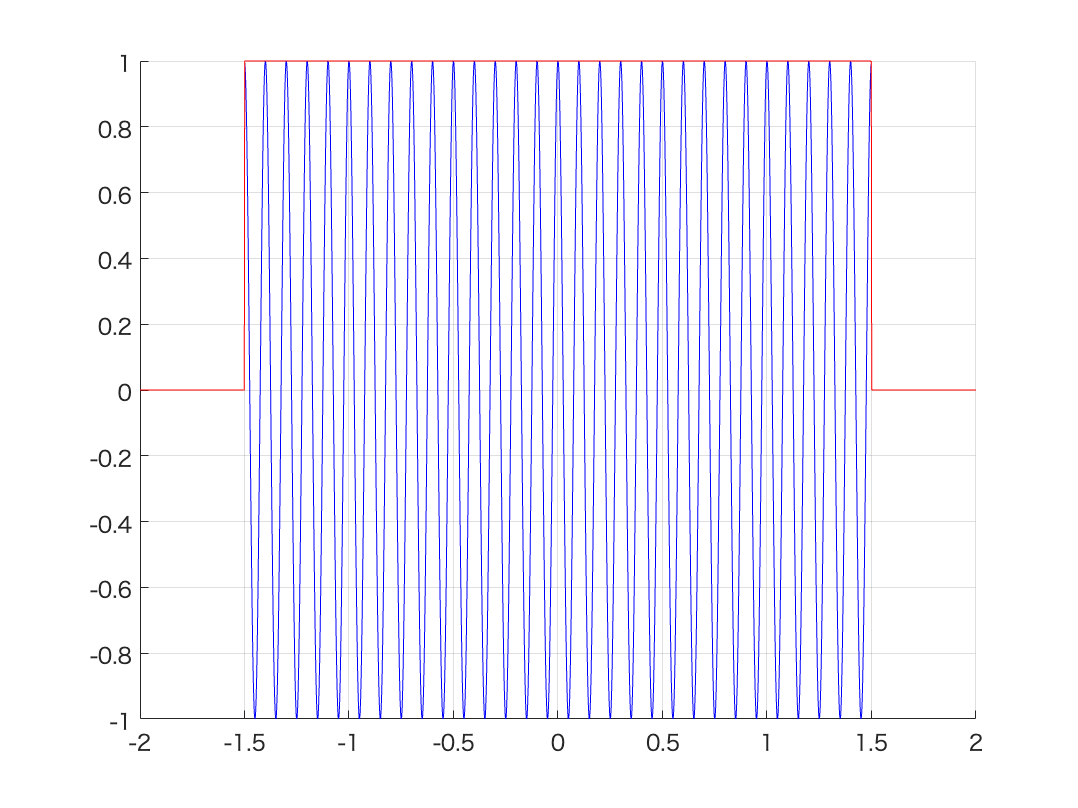

clf
fc = 10;
T = 3;
B = 2;
A = 1;

t = -2:0.001:2;
x = A * rectangularPulse(-T/2, T/2, t) .* cos(2*pi*fc*t);
h = A * rectangularPulse(-T/2, T/2, t);

hold on
plot(t, x, "b")
plot(t, h, "r")
grid on 

clf


$$ans = \left(\begin{array}{ccc} 1 & 2 & 3 \end{array}\right)$$

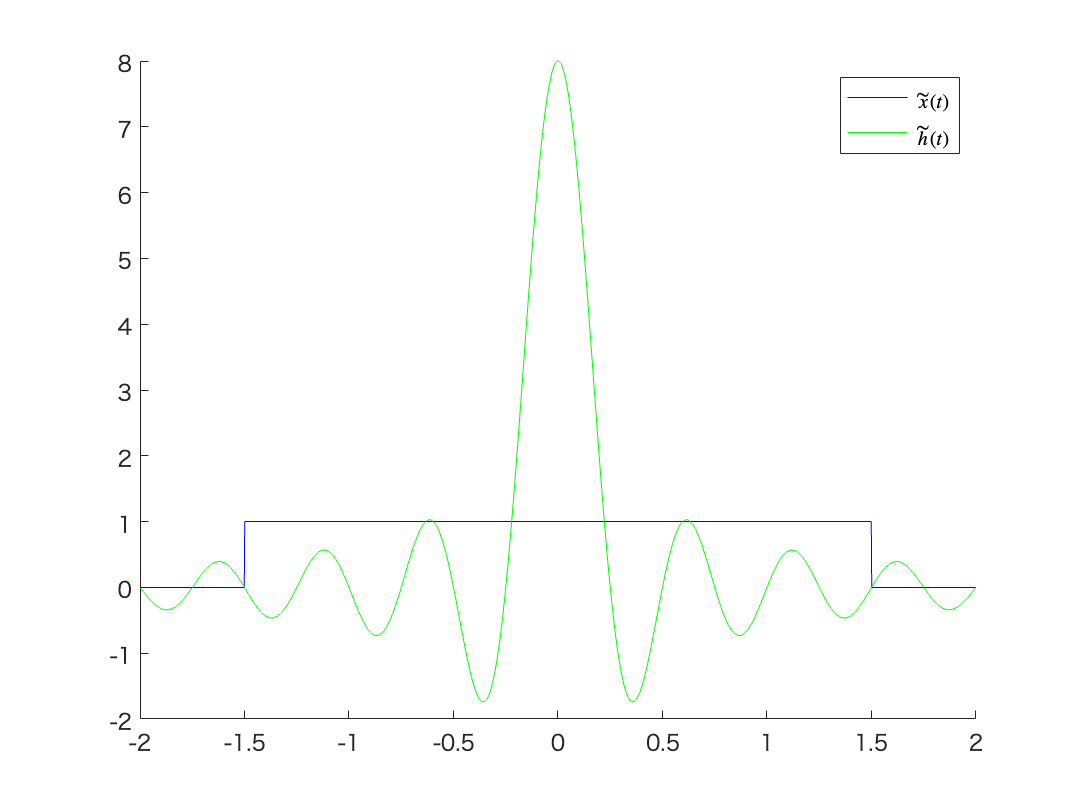

h_tilde = 4 * B * sinc(sym(2*B*t));
x_tilde = A * rectangularPulse(-T/2, T/2, t);
hold on
plot(t, x_tilde, "b")
plot(t, h_tilde, "g")
legend('$\tilde{x}(t)$', '$\tilde{h}(t)$', 'Interpreter', 'latex')

clf
y_tilde = conv(h_tilde, x_tilde);

次を使用中のエラー: conv2
データ型が無効です。最初の引数と 2 番目の引数は数値または論理値でなければなりません。

エラー: conv (行 32)
    c = conv2(a(:),b(:));

y_tilde = y_tilde(2000:6000);
plot(t, y_tilde)
legend('$\tilde{y}$', 'Interpreter', 'latex')

clf
y = real(y_tilde.*exp(1j*2*pi*fc*t));

関数または変数 'y_tilde' が認識されません。

plot(t, y)


type (h_tilde)

次を使用中のエラー: type
Arguments must be character vectors or strings